## Tarea 4

## Alejandro Brenes Calderón - C21319

## Santiago Fernández Sáenz - C22943

**1. **Considere el Algoritmo 1 para obtener la forma de Hessenberg $$H$$ de una matriz $$A$$ dada.

**a)**

Se realiza la función para obtener la matriz de Hessenberg correnpondiente.

function H = Hessenberg(A)
% Se define la matriz inicial
H = A;

% Dimensión de la matriz
m = size(A, 1);

% Ciclo para convertir iterativamente la matriz
for k = 1:(m - 2)
    % Vector columna de H
    x = H(((k + 1):m), k);

    % Vector canónico
    e = zeros(size(x, 1), 1);
    e(1) = 1;

    % Vector vk
    vk = sign(x(1)) .* norm(x, 2) .* e + x;

    % Se normaliza el vector vk
    vk = (vk / norm(vk, 2));

    % Modificación de la matriz H
    H(((k + 1):m), (k:m)) = H(((k + 1):m), (k:m)) - 2 .* vk .* (vk' * H(((k + 1):m), (k:m)));
    H((1:m), ((k + 1):m)) = H((1:m), ((k + 1):m)) - 2 .* (H((1:m), ((k + 1):m)) * vk) .* vk';
end
end

**b)**

Procedemos con el algoritmo pedido.

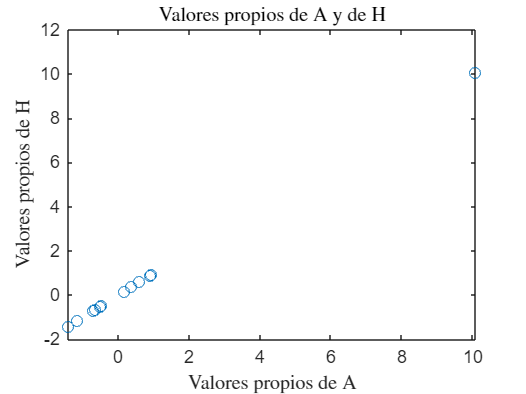

format long

% Matriz A
A = rand(20, 20);

% Se usa el algoritmo para obtener la forma de Hessenberg
H = Hessenberg(A);

% Valores propios
vp_A = eig(A);
vp_H = eig(H);

% Se muestra el gráfico correspondiente
figure;
plot(real(vp_A), real(vp_H), 'o')
title('Valores propios de A y de H', 'Interpreter', 'latex')
xlabel('Valores propios de A', 'Interpreter', 'latex');
ylabel('Valores propios de H', 'Interpreter', 'latex');


% Diferencia de los valores propios
error = norm(abs(vp_H - vp_A), 2);
fprintf('El error de los valores propios: %.16f\n', error);

El error de los valores propios: 0.0000000000000081


**2. **(Secuencias de Sturm)

**a)**

function [seqsturm, concordancias] = sequenciasturm(a, b, theta)
    
    m = length(a);
    
    % Completar la secuencia de sturm
    p = zeros(m+1, 1);
    p(1) = 1;          % Condición inicial
    p(2) = a(1) - theta;
    
    for k = 2:m
        if k <= length(b)
            p(k+1) = (a(k) - theta) * p(k) - b(k)^2 * p(k-1);
        else
            p(k+1) = (a(k) - theta) * p(k);
        end
    end
    
    % Ignorar el primer valor (p(1) no pertenece a la secuencia real)
    seqsturm = p(2:end);
    
    % Calcular el número de concordancias
    signs = sign(seqsturm);  % Signos de los elementos

    % Reemplazamos los 0 de los signos por el anterior elemento
    for i = 2:length(signs)
        if signs(i) == 0
            signs(i) = signs(i-1);
        end
    end

    % Contar pares con el mismo signo
    concordancias = sum(diff(signs) == 0);
end

**b.**

% Contador de valores propios menores que theta
function cantidad = contador_valores_propios(a, b, theta)
    [~, concordancias] = sequenciasturm(a, b, theta);
    cantidad = length(a) - concordancias;
end

function [lambda_min, lambda_max] = sturm_biseccion(a, b, tol)

    % Intervalo por teorema de Gershgorin
    limite_inf = min(a) - 2 * max(abs(b)); %2
    limite_sup = max(a) + 2 * max(abs(b)); %6

    % Encontrar el valor propio mínimo
    a_min = limite_inf;
    b_min = limite_sup;
    while (b_min - a_min) > tol
        punto_medio = (a_min + b_min) / 2;
        if contador_valores_propios(a, b, punto_medio) > 0
            b_min = punto_medio;
        else
            a_min = punto_medio;
        end
    end
    lambda_min = (a_min + b_min) / 2;

    % Encontrar el valor propio máximo
    a_max = limite_inf;
    b_max = limite_sup;
    total_valores_propios = length(a);
    while (b_max - a_max) > tol
        punto_medio = (a_max + b_max) / 2;
        if contador_valores_propios(a, b, punto_medio) < total_valores_propios
            a_max = punto_medio;
        else
            b_max = punto_medio;
        end
    end
    lambda_max = (a_max + b_max) / 2;
end

Implementacion en la matriz T

%Parámetros
m = 1e6;                 
a = 4 * ones(m, 1);     
b = -1 * ones(m-1, 1);   
tol = 1e-6;

% Vectores para índices y valores
i = [1:m, 2:m, 1:m-1]';  
j = [1:m, 1:m-1, 2:m]';  
s = [a; b; b];           

% Generar matriz dispersa T
T = sparse(i, j, s, m, m);

% Calcular valores propios extremos
[lambda_min, lambda_max] = sturm_biseccion(a, b, tol);

fprintf('Valor propio mínimo: %.6f\n', lambda_min);

Valor propio mínimo: 2.000000


fprintf('Valor propio máximo: %.6f\n', lambda_max);

Valor propio máximo: 6.000000


**c)**

lambda_max = eigs(T, 1, 'LM');


% Encontrar el valor propio de menor magnitud
lambda_min = eigs(T, 1, 'SM');


% Mostrar resultados
fprintf('Valor propio mayor: %.6f\n', lambda_max);

Valor propio mayor: NaN


fprintf('Valor propio menor: %.6f\n', lambda_min);

Valor propio menor: NaN


La matriz indica que el los valores propios no convergen a nada. En este caso las dimensiones de las matrices son muy grandes y eso es un problema para esta funcion, ya que ni siquiera en una matriz 5000x5000 converge a un valor específico. 